# IDENTIFICACION DE UN MODELO ARX

clear all
close all

Datos = xlsread("Datos_Modelo_ARX.xlsx")

Datos =          0    1.0000         0
    0.5000    1.0000         0
    1.0000    1.0000         0
    1.5000    1.0000         0
    2.0000    1.0000         0
    2.5000    1.0000    0.2249
    3.0000    1.0000    0.7792
    3.5000    1.0000    1.4724
    4.0000    1.0000    2.1442
    4.5000    1.0000    2.6905



t = Datos(:,1);
U = Datos(:,2);
Y = Datos(:,3);

subplot(2,1,1)
plot(t,U,'*','MarkerSize',4) %La entrada es un escalon unitario porque inica a t = 0 
ylabel('Entrada')
xlabel('Muestras')
grid on

subplot(2,1,2)
plot(t,Y,'o r','MarkerSize',4)
ylabel('Entrada')
xlabel('Muestras')
grid on
hold on

%Se seleccionara na = 3, nb = 3, d = 3
N = length(Y);
X = [-[0;Y(1:N-1)], -[0;0;Y(1:N-2)],-[0;0;0;Y(1:N-3)], [0;0;0;U(1:N-3)], [0;0;0;0;U(1:N-4)],[0;0;0;0;0;U(1:N-5)]]

X =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    1.0000         0         0
         0         0         0    1.0000    1.0000         0
         0         0         0    1.0000    1.0000    1.0000
   -0.2249         0         0    1.0000    1.0000    1.0000
   -0.7792   -0.2249         0    1.0000    1.0000    1.0000
   -1.4724   -0.7792   -0.2249    1.0000    1.0000    1.0000
   -2.1442   -1.4724   -0.7792    1.0000    1.0000    1.0000



%Matriz de covarianzas

Q = X'*X

Q =   238.1879  232.7900  225.7287  -80.5034  -80.5034  -80.5034
  232.7900  229.1964  223.7964  -77.5048  -77.5048  -77.5048
  225.7287  223.7964  220.2008  -74.5055  -74.5055  -74.5055
  -80.5034  -77.5048  -74.5055   32.0000   31.0000   30.0000
  -80.5034  -77.5048  -74.5055   31.0000   31.0000   30.0000
  -80.5034  -77.5048  -74.5055   30.0000   30.0000   30.0000



%Vector  de parámetros
Theta = inv(Q)*X'*Y

Theta =    -2.0220
    1.4994
   -0.3914
    0.0000
    0.0000
    0.2590


a1 = Theta(1);
a2 = Theta(2);
a3 = Theta(3);
b0 = Theta(4);
b1 = Theta(5);
b2 = Theta(6);

%Estos se regresan como función de transferencia



$$\textrm{Gp}\left(z\right)=\frac{b_0 z^3 +b_1 z^2 +b_2 z}{z^3 +a_1 z^2 +a_2 z+a_3 }z^{-3}$$


z = tf('z',t(2)-t(1))

z =
 
  z
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties



Gpz = ((b0*z^3 + b1*z^2 + b2*z)/(z^3 + a1*z^2 +a2*z + a3))*z^(-3)

Gpz =
 
  1.098e-14 z^3 + 3.872e-14 z^2 + 0.259 z
  ----------------------------------------
  z^6 - 2.022 z^5 + 1.499 z^4 - 0.3914 z^3
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


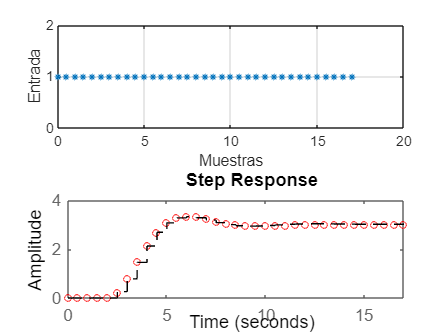


step(Gpz, 'k--',t(end))

Ymodel = step(Gpz, t(end))

Ymodel =          0
         0
         0
    0.0000
    0.0000
    0.2590
    0.7827
    1.4532
    2.1252
    2.6836


% Ajuste de error - Coeficiente de correlacion
Sy = sum((Y-mean(Y)).^2)

Sy = 47.9629

Sr = sum((Y-Ymodel).^2)

Sr = 0.0225

R2 = (Sy - Sr)/Sy 

R2 = 0.9995